# MATLAB Image Processing Basics - Lab 2: From Noisy Mask to Real Analysis

**Computer Applications in Transportation (2101553)**

**Siwarak Unsiwilai, Ph.D.**

Email: [siwarak.u@chula.ac.th](mailto:siwarak.u@chula.ac.th) Office: CE Building, Room 534

**Learning Objectives:**

- Apply **filtering **to pre-process a grayscale image and reduce noise.

- Use **morphological operations** to clean a binary mask.

- Perform **Image Analysis **to count objects and extract data.

## Initial Step: Check for Required Toolbox

As in Week 1, we first check if the Image Processing Toolbox is installed.

%% Initial Step: Check for Required Toolbox
% This lab requires the Image Processing Toolbox. Let's check if it's installed.

% Clear workspace for a fresh start
clear all;
clc;
close all;

% --- Toolbox Check ---
% Use 'ver' to get version info for all toolboxes
toolbox_info = ver;

% Check if 'Image Processing Toolbox' is in the list of names
is_installed = any(strcmp({toolbox_info.Name}, 'Image Processing Toolbox'));

% *** CORRECTED LOGIC ***
if is_installed
    disp('Success: Image Processing Toolbox is installed.');
    disp('You can run the rest of the script.');
else
    % If not installed, stop the script and show an error
    error(['Image Processing Toolbox not found. Please install it to continue.' ...
           '\n\nTo install:' ...
           '\n1. Go to the Home tab' ...
           '\n2. Click Add-Ons > Manage Add-Ons' ...
           '\n3. Search for "Image Processing Toolbox" and install it.' ...
           '\n4. Restart MATLAB and run this script again.']);
end

Success: Image Processing Toolbox is installed.


You can run the rest of the script.


## Recap: Our 5-Step Pipeline Goal

Last week, we started building the 5-step image processing pipeline but ended with a "noisy" mask. 

Today, we will complete all five steps to get an accurate count of the rice grains.

### Step 1: Acquisition (The "Done" Step)

We start by loading our image. This step is complete.

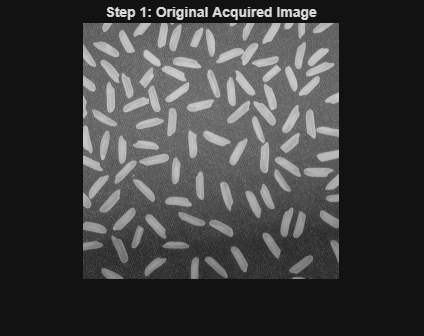

% --- STAGE 1: ACQUISITION ---

full_path = which('rice.png');
img = imread(full_path);

figure;
imshow(img);
title('Step 1: Original Acquired Image');

### Step 2: Pre-processing - Comparing Filters

Last week, we skipped this step. Pre-processing cleans the original grayscale image (`img`) to make our segmentation more accurate. 

Let's compare three common filter types to see which works best on our image.

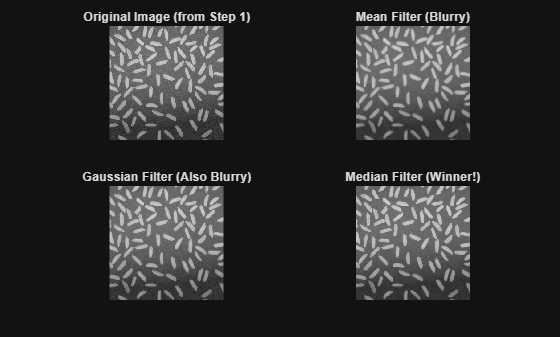

% --- STAGE 2: PRE-PROCESSING ---
% 'img' is already in our workspace from Step 1.

% --- Filter 1: Averaging (Mean) Filter (with default setup) ---
% This kernel averages all pixels in a 3x3 window.
h_mean = fspecial('average', [3,3]);
img_mean = imfilter(img, h_mean);

% --- Filter 2: Gaussian Filter (with default setup) ---
% This is a "weighted" average, blurring more smoothly.
img_gaussian = imgaussfilt(img, 0.5); % Default sigma

% --- Filter 3: Median Filter (with default setup) ---
% This takes the median (middle) value of a 3x3 window.
img_median = medfilt2(img); % Default [3 3]

% --- Display Comparison ---
figure;
subplot(2, 2, 1);
imshow(img);
title('Original Image (from Step 1)');

subplot(2, 2, 2);
imshow(img_mean);
title('Mean Filter (Blurry)');

subplot(2, 2, 3);
imshow(img_gaussian);
title('Gaussian Filter (Also Blurry)');

subplot(2, 2, 4);
imshow(img_median);
title('Median Filter (Winner!)');

**Observation:**

- The **Mean** and **Gaussian** filters just blurred the noise; they didn't remove it.

- The **Median Filter** did the best job. Because the noise is an outlier, the median value ignores it, effectively removing the specks while keeping the rice edges sharp .

**Conclusion:** For "salt-and-pepper" noise, the `medfilt2` function is our best choice.

### Step 2: Pre-processing (Continued) - Fine-Tuning the Median Filter

Now that we've chosen `medfilt2`, let's do a "deep dive" and tune its main parameter: the **neighborhood size**. 

The default is `[3 3]`. What happens if we make it bigger?

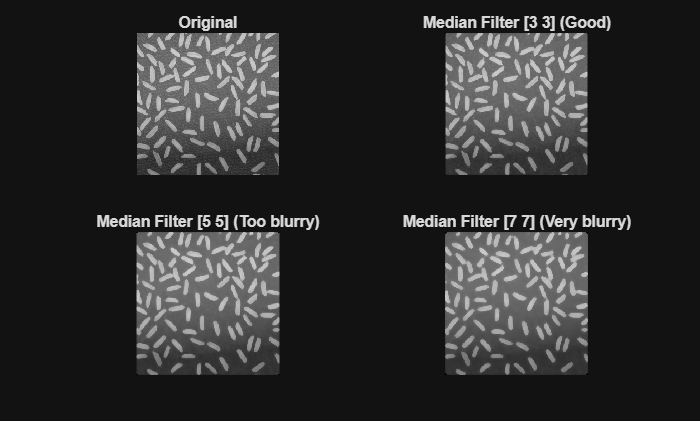

% --- Fine-Tuning medfilt2 ---
% We still use the original 'img' from Step 1.

% 1. Default 3x3 neighborhood
img_median_3x3 = medfilt2(img, [3 3]);

% 2. Larger 5x5 neighborhood
img_median_5x5 = medfilt2(img, [5 5]);

% 3. Even larger 7x7 neighborhood
img_median_7x7 = medfilt2(img, [7 7]);

% --- Display Comparison ---
figure;
subplot(2, 2, 1);
imshow(img);
title('Original');

subplot(2, 2, 2);
imshow(img_median_3x3);
title('Median Filter [3 3] (Good)');

subplot(2, 2, 3);
imshow(img_median_5x5);
title('Median Filter [5 5] (Too blurry)');

subplot(2, 2, 4);
imshow(img_median_7x7);
title('Median Filter [7 7] (Very blurry)');

**Observation:**

- The `[3 3]` filter does a good job of removing noise without damaging the rice.

- The `[5 5]` and `[7 7]` filters remove the noise, but they also start to blur and distort the rice grains themselves.

**Supplementary Note: Tuning Padding (Advanced)**

The *neighborhood size* is the main parameter. For advanced control, you can also tune the **padding option** (what to do at the image borders).

Let's see the difference. The default pads with black (`'zeros'`), which can create an artificial dark border. A better option is often `'symmetric'`, which pads by reflecting the image.

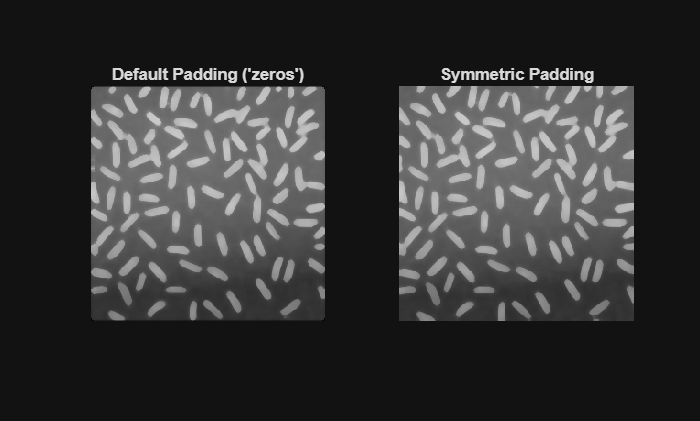

% --- Advanced: Tuning Padding ---
% We'll use a [7 7] filter to make the edge effect easy to see.

% 1. Default padding ('zeros')
img_pad_zeros = medfilt2(img, [7 7]); 
% You can also write: medfilt2(img, [7 7], 'zeros');

% 2. Symmetric padding
img_pad_symmetric = medfilt2(img, [7 7], 'symmetric');

% --- Display Comparison ---
figure;
subplot(1, 2, 1);
imshow(img_pad_zeros);
title('Default Padding (''zeros'')');

subplot(1, 2, 2);
imshow(img_pad_symmetric);
title('Symmetric Padding');

**Final Decision:** The default `medfilt2(img)` (which is `[3 3]` with `'zeros'` padding) is the best and simplest choice. We will create a new variable, `img_preprocessed`, to hold this result for the next step.

% Create our final pre-processed image for the next step
img_preprocessed = medfilt2(img);

### Step 3: Segmentation - Revisiting Week 1 and Analyzing Our Filtered Image

This is a step we already know from Week 1: `imhist` and `imbinarize`.

Let's compare the **image and its histogram** side-by-side for both our original `img` and our new `img_preprocessed`. This will clearly show *why* the filtered image gives a cleaner segmentation.

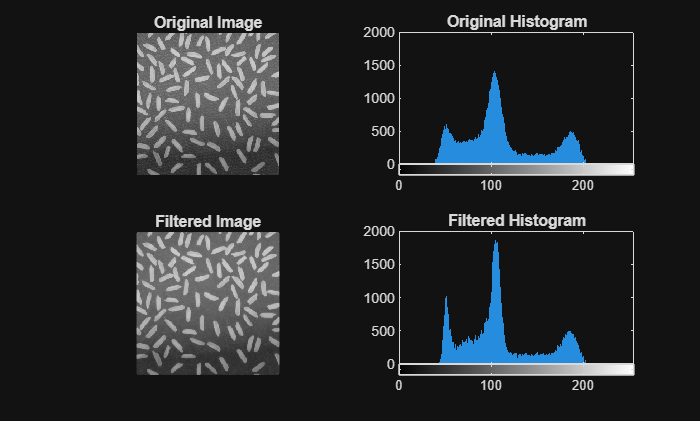

% --- STAGE 3: SEGMENTATION ---
% 'img' is our original image.
% 'img_preprocessed' is our clean one from Step 2.

% --- Image & Histogram Comparison ---
figure;
% Top row: Original Image & its Histogram
subplot(2, 2, 1);
imshow(img);
title('Original Image');

subplot(2, 2, 2);
imhist(img);
title('Original Histogram');
ylim([0 2000]);

% Bottom row: Pre-processed Image & its Histogram
subplot(2, 2, 3);
imshow(img_preprocessed);
title('Filtered Image');

subplot(2, 2, 4);
imhist(img_preprocessed);
title('Filtered Histogram');
ylim([0 2000]);

**Observation:**

- Look at the "Filtered Histogram" (bottom right). It's much **sharper** than the "Original Histogram" (top right).

- The `medfilt2` function "cleaned up" the outlier noise pixels, grouping them back into the two main humps.

- The "valley" between the dark background (left hump) and the light rice (right hump) is now **cleaner and more defined**. This makes finding a single threshold (like Otsu's method does) much more effective.

Now, let's apply the thresholding to see the final result of this step.

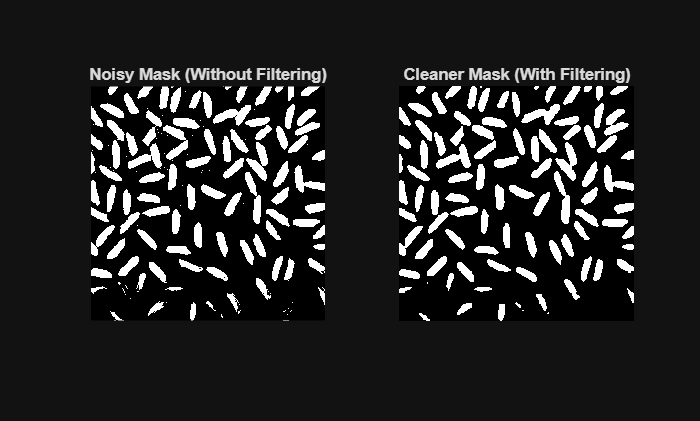

% --- Thresholding Comparison ---
% Get the automatic threshold from our new, cleaner image
T_norm = graythresh(img_preprocessed);

% 1. Create the "noisy" mask from last week (using original 'img' and its own threshold)
BW_noisy = imbinarize(img, graythresh(img));

% 2. Create our new, cleaner mask (using 'img_preprocessed')
BW_cleaner = imbinarize(img_preprocessed, T_norm);

% --- Display Comparison ---
figure;
subplot(1, 2, 1);
imshow(BW_noisy);
title('Noisy Mask (Without Filtering)');

subplot(1, 2, 2);
imshow(BW_cleaner);
title('Cleaner Mask (With Filtering)');

**Observation:**

- The pre-processing step made a **huge difference**.

- The "Cleaner Mask" (on the right) has almost no "salt-and-pepper" noise in the background.

- **However**, as you can see, it's still not *perfect*. There are still some small black holes inside the rice grains. This means we need to move to the next step to clean the mask itself.

### Step 4: Feature Extraction - Morphological Cleaning

Our `BW_cleaner` mask from Step 3 is good, but it has two problems:

- Small white noise specks in the background.

- Small black holes inside the rice.

We will use `imopen` to solve Problem 1. We will **ignore Problem 2** for now and fix it in Step 6.

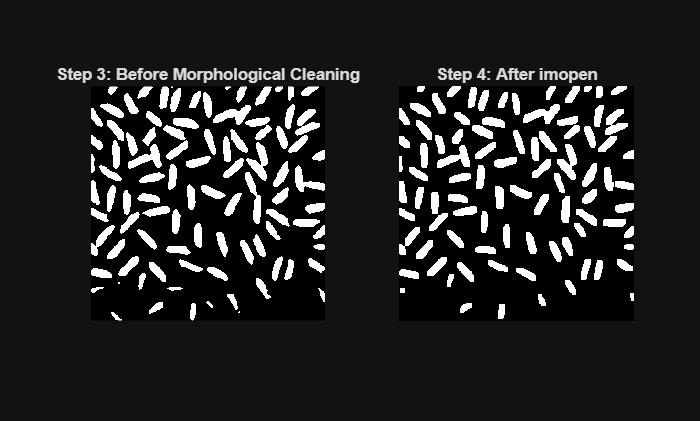

% --- STAGE 4: MORPHOLOGICAL CLEANING ---
% 'BW_cleaner' is our best mask so far from Step 3.

% 1. Define our "cleaning brush"
se = strel('disk', 3); % A 3-pixel radius is good

% 2. Apply Image Opening to remove background noise
% imopen = Erode, then Dilate. This removes small white "islands".
BW_final_mask = imopen(BW_cleaner, se);

% --- Display the Result ---
figure;
subplot(1, 2, 1);
imshow(BW_cleaner);
title('Step 3: Before Morphological Cleaning');

subplot(1, 2, 2);
imshow(BW_final_mask);
title('Step 4: After imopen');

**Observation:**

- The mask in Step 4 is much cleaner. The background noise is gone.

- However, the **black holes** inside the rice grains are still there.

### Step 5: Inference/Decision - Counting and Analysis

Now we run our analysis functions on this new `BW_final_mask`.

% --- STAGE 5: ANALYSIS ---

% 1. Find all connected "blobs"
% This will find the rice grains AND the small holes.
cc = bwconncomp(BW_final_mask);

% 2. Get properties for all blobs
stats = regionprops(cc, 'Area', 'Centroid');

% 3. Get the count (after imopen)
num_after_imopen = cc.NumObjects;
fprintf('Count (after imopen): %d\n', num_after_imopen);

Count (after imopen): 88


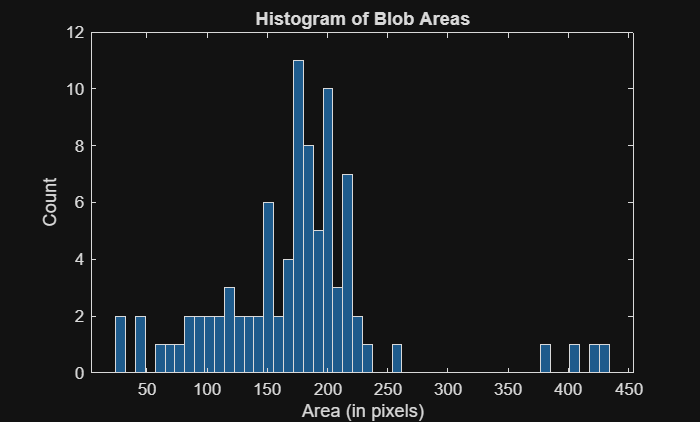


% 4. Plot the histogram of all blob areas
figure;
histogram([stats.Area], 50);
title('Histogram of Blob Areas');
xlabel('Area (in pixels)');
ylabel('Count');

**Observation: **The histogram now clearly shows two groups:

- A large "hump" of **small blobs** (the black holes we *didn't* fill).

- A large "hump" of **big blobs** (the actual rice grains).

### **Step 6: **Filtering by Area (The *Real* Solution)

Now, we can use the "filter by area" trick to solve *both* problems at once:

- It will remove any leftover **noise specks** (small white blobs).

- It will remove all the **black holes** (which `bwconncomp` also sees as "blobs" if we were to invert the image, but `regionprops` on the *white* blobs just sees them as small).

Let's just keep the blobs that are "rice-sized."

% --- STAGE 6: FILTERING BY AREA ---
% 'stats' is our data from Step 5

% 1. Set an area threshold.
% Based on the histogram, a value of 30 looks like a good cutoff.
MIN_AREA_THRESHOLD = 30;

% 2. Filter our 'stats' table to keep only the large blobs
stats_clean = stats([stats.Area] > MIN_AREA_THRESHOLD);

% 3. Get the new, more accurate count
num_rice_clean = length(stats_clean);

fprintf('Original (after imopen) Count: %d\n', num_after_imopen);

Original (after imopen) Count: 88


fprintf('Final (Cleaned) Count: %d\n', num_rice_clean);

Final (Cleaned) Count: 86


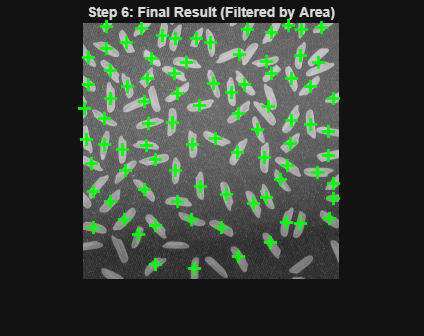


% 4. Display the new, cleaner plot
figure;
imshow(img); % Show the original 'img' from Step 1
title('Step 6: Final Result (Filtered by Area)');
hold on;

% Loop through only the CLEAN blobs
for i = 1:num_rice_clean
    plot(stats_clean(i).Centroid(1), stats_clean(i).Centroid(2), 'g+', 'MarkerSize', 10, 'LineWidth', 2);
end
hold off;

**Observation:**Looking at the "Step 6: Final Result" image, our pipeline is much better, but it's still not perfect.

- **The Good:** We have successfully filtered out all the small "noise" specks and "hole" blobs. The markers are only on large objects.

- **The Bad:** There are still two big problems:

- **Missed Grains:** Many grains, especially in the darker bottom-right corner, have no marker at all.

- **Merged Grains:** Some grains that are close together (like the two in the bottom-right) are being incorrectly treated as *one* large blob, resulting in a single, badly placed marker.

**Conclusion:**Our "post-processing" filter (filtering by area) was a good idea, but it can't fix errors that happened during **Segmentation (Step 3)**.

The root cause of our problem is the **uneven lighting** in the `rice.png` image. Our "global" `graythresh` function in Step 3 isn't smart enough to handle this. It finds one threshold for the whole image, causing it to lose the grains in the dark areas.

To fix this, we must use a more advanced segmentation technique. In **Step 7**, we will replace our "global" threshold with an **"Adaptive Threshold"** to see if we can detect those missing grains.

### **Step 7: Fixing Missed Grains with Adaptive Thresholding**

Our "area filtering" in Step 6 was a good *post-processing* step, but it can't fix grains that were never detected in the first place.

**Observation from Step 6:** We missed many grains in the darker (bottom-right) part of the image.

**Root Cause:** The image has **uneven lighting**. Our "global" `graythresh` function in Step 3 isn't smart enough to handle this. It finds one threshold for the whole image, causing it to lose the grains in the dark areas. 

**Solution:** We will replace our "global" threshold with a *local* one. This is called **Adaptive Thresholding**.

**7.1 Global vs. Adaptive Thresholding**

Let's compare the `imbinarize` function using its two different modes:

- **Global (Otsu's):** Uses `graythresh` to find one threshold for the entire image.

- **Adaptive:** Calculates a *different, local* threshold for small neighborhoods as it slides over the image.

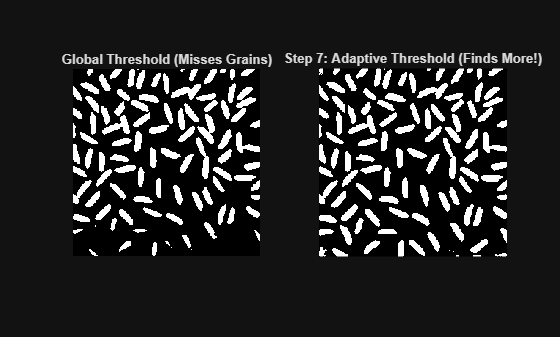

% --- STAGE 7: ADAPTIVE THRESHOLDING ---
% 'img_preprocessed' is our clean image from Step 2.

% 1. Our old "global" threshold (for comparison)
T_norm_global = graythresh(img_preprocessed);
BW_global = imbinarize(img_preprocessed, T_norm_global);

% 2. The NEW "adaptive" threshold
% We are removing 'NeighborhoodSize' as your MATLAB version
% does not support that parameter name.
% We set 'Sensitivity' to fine-tune it.
BW_adaptive = imbinarize(img_preprocessed, 'adaptive', 'Sensitivity', 0.5);

% --- Display Comparison ---
figure;
subplot(1, 2, 1);
imshow(BW_global);
title('Global Threshold (Misses Grains)');

subplot(1, 2, 2);
imshow(BW_adaptive);
title('Step 7: Adaptive Threshold (Finds More!)');

**Observation:**

- The **"Global Threshold"** image (left) is black in the bottom-right, losing all those grains.

- The **"Adaptive Threshold"** image (right) successfully finds the grains *even in the dark areas*.

- **The Trade-off:** The adaptive method is *much noisier*. But our pipeline (Steps 4-6) is strong enough to handle this.

**7.2 The Full Pipeline (with Adaptive Thresholding)**

Now, let's run our *entire* robust pipeline (Steps 4, 5, and 6) on this new, noisy `BW_adaptive` mask.

% --- Run Steps 4, 5, and 6 on the new adaptive mask ---

% Step 4: Clean the new (noisier) mask
% 'imopen' is excellent at removing all the new background noise.
se = strel('disk', 3);
BW_opened = imopen(BW_adaptive, se);

% Step 5: Analyze the blobs
cc = bwconncomp(BW_opened);
stats = regionprops(cc, 'Area', 'Centroid');

% Step 6: Filter by area
% We'll use the same area threshold as before.
stats_clean = stats([stats.Area] > 30);
num_rice_clean = length(stats_clean);

fprintf('Final (Adaptive) Count: %d\n', num_rice_clean);

Final (Adaptive) Count: 97


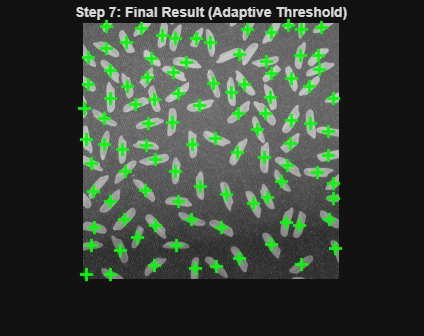


% --- Final Visualization ---
figure;
imshow(img);
title('Step 7: Final Result (Adaptive Threshold)');
hold on;
for i = 1:num_rice_clean
    plot(stats_clean(i).Centroid(1), stats_clean(i).Centroid(2), 'g+', 'MarkerSize', 10, 'LineWidth', 2);
end
hold off;

**Observation: **Looking at our final result, the `imbinarize('adaptive')` method was a **major improvement** over the "global" `graythresh`.

- **The Good:** We successfully detected most of the grains, even in the dark corners where they were missed before.

- **The Bad:** The result is still not perfect.

**                A. Missed Grains:** A few grains are still missed.

**                B. Merged Grains:** The adaptive threshold *still* merged some     

        touching grains. We can see several centroids that are badly placed between two grains.

**Final Conclusion:**We have demonstrated the entire engineering process of **iterative tuning**.

- **Step 3 (Global Threshold):** Failed on uneven lighting.

- **Step 6 (Post-processing):** Cleaned up noise, but couldn't fix the missed grains.

- **Step 7 (Adaptive Threshold):** Fixed the *missed grain* problem, but still couldn't solve the *merged grain* problem.

This shows the limit of threshold-based methods. To get a perfect result, we would need to go back and try an even more advanced technique, like the **Marker-Controlled Watershed**, or combine our adaptive threshold with different `imopen` parameters to try and break the merged grains apart.